# Mapa logistico

function S = logisticSequence(seed, alpha, N0, N)

x = seed;
S = zeros(1, N + N0);

for k = 1:(N + N0)
    x = alpha * x * (1 - x);
    S(k) = x;
end

% eliminar transitorio
S = S(N0+1:end);

end

# Ordenamiento

function perm = getPermutationFromChaos(S)

[~, perm] = sort(S, 'ascend');

end

# Permutacion intra bit

function [bp_perm, Gmask, perm] = intraBitPermutation(bp, seed)

[filas, columnas] = size(bp);
N = filas * columnas;

% parámetros del paper
alpha = 3.99999;
N0 = 1000;

% 1. secuencia caótica
S = logisticSequence(seed, alpha, N0, N);

% 2. obtener permutación
perm = getPermutationFromChaos(S);

% 3. aplicar permutación
vector = bp(:);
vector_perm = vector(perm);

bp_perm = reshape(vector_perm, filas, columnas);

% 4. calcular máscara G (XOR)
Gmask = xor(bp, bp_perm);

end

# Permutacion Interbit

function [bitplanes_out, pairs] = interBitPermutation(bitplanes, seed)

[filas, columnas, numBits] = size(bitplanes);

% Parámetros del mapa logístico
alpha = 3.99999;
N0 = 1000;

% generar secuencia caótica
S = logisticSequence(seed, alpha, N0, numBits);

% obtener orden caótico de planos
[~, order] = sort(S,'ascend');

bitplanes_out = bitplanes;

pairs = [];

% aplicar XOR entre pares de planos
for k = 1:2:(numBits-1)
    
    b1 = order(k);
    b2 = order(k+1);
    
    bitplanes_out(:,:,b2) = xor(bitplanes_out(:,:,b2), bitplanes_out(:,:,b1));
    
    pairs = [pairs; b1 b2];
    
end

end

# Compuertas not

function qc = buildIntraBitCircuit(Gmask)

[filas, columnas] = size(Gmask);
N = filas * columnas;

gates = [];

index = 1;

for i = 1:filas
    for j = 1:columnas
        
        if Gmask(i,j) == 1
            gates = [gates; xGate(index)];
        end
        
        index = index + 1;
    end
end

qc = quantumCircuit(gates, Name="IntraBit");

end

# Difusion Caotica

function img_diff = chaoticDiffusion(img, seed)

[filas, columnas] = size(img);
N = filas * columnas;

alpha = 3.99999;
N0 = 1000;

%% Generar secuencia caótica

S = logisticSequence(seed, alpha, N0, N);

% convertir a valores 0-255
K = uint8(floor(S * 256));

%% vectorizar imagen

P = img(:);

C = zeros(N,1,'uint8');

%% difusión

C(1) = bitxor(P(1), K(1));

for i = 2:N
    
    C(i) = bitxor(bitxor(P(i), K(i)), C(i-1));
    
end

%% reconstruir imagen

img_diff = reshape(C, filas, columnas);

end

# Encriptacion

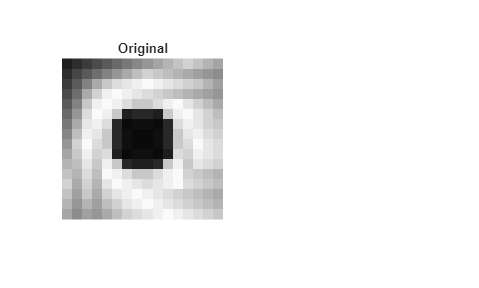

clc; clear; close all;

%% Leer imagen
%%img = imread('C:\Users\marlo\OneDrive\Documentos\Mis documentos\UD\COMPLEX\pepers.jpg');
img = uint8([ ...
 30  45  60  75  90 105 120 135 150 165 180 195 210 195 180 165;
 45  70  90 110 130 150 170 190 210 200 190 180 170 160 150 140;
 60  90 130 170 200 220 230 240 250 240 230 220 210 200 180 160;
 75 110 170 210 240 250 240 230 220 210 200 190 180 170 160 150;
 90 130 200 240 250 240 220 200 200 220 240 250 230 210 190 170;
105 150 220 250 240 200  30  40  40  30 200 240 250 230 210 190;
120 170 230 240 220  40  10  15  15  10  40 220 240 230 210 200;
135 190 240 230 200  40  15  10  10  15  40 200 230 240 220 210;
150 210 250 220 200  40  15  10  10  15  40 200 220 250 230 220;
165 200 240 210 220  30  10  15  15  10  30 220 210 240 230 220;
180 190 230 200 240 200  40  30  30  40 200 240 200 230 220 210;
195 180 220 190 250 240 220 200 200 220 240 250 210 200 190 180;
210 170 210 180 230 250 240 230 220 230 240 250 220 210 200 190;
195 160 200 170 210 230 240 250 240 230 220 210 200 190 180 170;
180 150 180 160 190 210 230 240 250 240 230 220 210 200 190 180;
165 140 160 150 170 190 210 220 230 240 250 240 230 220 210 200
]);

rojo = img(:,:,1);

subplot(1,2,1); imshow(img);   title('Original');

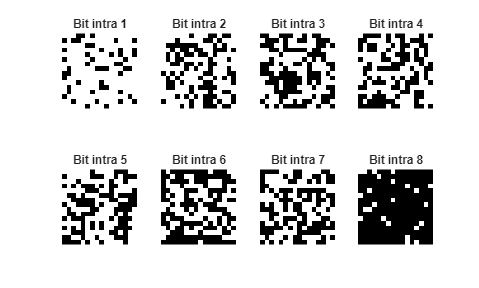

%% Obtener planos de bits

[filas, columnas] = size(rojo);
rojo_bin = zeros(filas, columnas, 8);

for k = 1:8
    rojo_bin(:,:,k) = bitget(rojo, 9-k);
end

%% ===== PERMUTACIÓN INTRA BIT =====

seeds = [0.5 0.52 0.53 0.6 0.37 0.46 0.38 0.61];

rojo_perm = zeros(size(rojo_bin));
circuits = cell(1,8);

for k = 1:8
    
    bp = rojo_bin(:,:,k);
    
    [bp_perm, Gmask, perm] = intraBitPermutation(bp, seeds(k));
    
    rojo_perm(:,:,k) = bp_perm;
    
    % circuito cuántico
    circuits{k} = buildIntraBitCircuit(Gmask);
    
end

%% Visualizar planos permutados

figure;
for k = 1:8
    subplot(2,4,k)
    imshow(rojo_perm(:,:,k))
    title(['Bit intra ', num2str(k)])
end

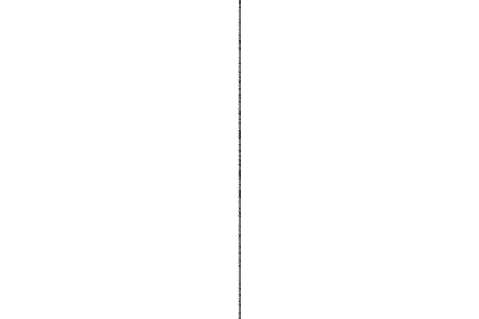

%% Mostrar un circuito de ejemplo
figure('Position', [100, 100, 2400, 1600]);  % [x, y, ancho, alto]
plot(circuits{1});
title('Circuito intra-bit plano 1');

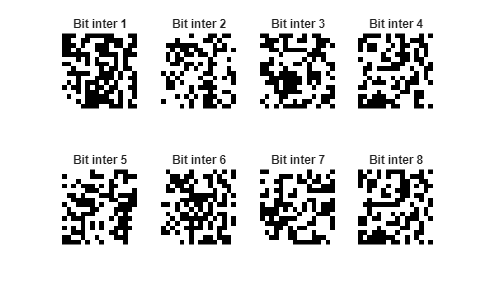

%% ===== PERMUTACIÓN INTER BIT =====

seed_inter = 0.73;

[rojo_inter, pairs] = interBitPermutation(rojo_perm, seed_inter);

%% Visualizar planos después de inter-bit

figure;

for k = 1:8
    
    subplot(2,4,k)
    imshow(rojo_inter(:,:,k))
    title(['Bit inter ', num2str(k)])
    
end

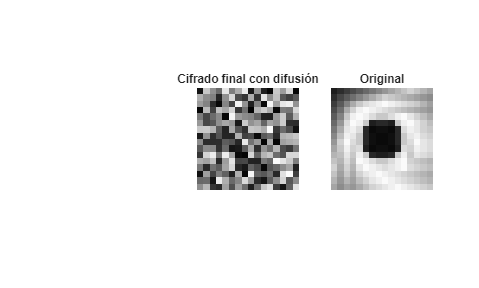

%% ===== RECONSTRUCCIÓN DE LA IMAGEN =====

img_cifrada = zeros(filas, columnas, 'uint8');

for k = 1:8
    
    img_cifrada = img_cifrada + uint8(rojo_inter(:,:,k)) * 2^(8-k);
    
end

%% ===== DIFUSIÓN CAÓTICA =====

seed_diff = 0.81;

img_diff1 = chaoticDiffusion(img_cifrada, seed_diff);
figure

subplot(1,3,2)
imshow(img_diff1)
title('Cifrado final con difusión')
subplot(1,3,3)
imshow(img)
title('Original')

# Difusion inversa

function img = inverseChaoticDiffusion(img_diff, seed)

[filas, columnas] = size(img_diff);
N = filas * columnas;

alpha = 3.99999;
N0 = 1000;

S = logisticSequence(seed, alpha, N0, N);

K = uint8(floor(S * 256));

C = img_diff(:);
P = zeros(N,1,'uint8');

P(1) = bitxor(C(1), K(1));

for i = 2:N
    
    P(i) = bitxor(bitxor(C(i), K(i)), C(i-1));
    
end

img = reshape(P, filas, columnas);

end

# Inversa interbit

function bitplanes = inverseInterBitPermutation(bitplanes, pairs)

for k = size(pairs,1):-1:1
    
    b1 = pairs(k,1);
    b2 = pairs(k,2);
    
    bitplanes(:,:,b2) = xor(bitplanes(:,:,b2), bitplanes(:,:,b1));
    
end

end

# Inversa intra bit

function bp = inverseIntraBitPermutation(bp_perm, perm)

[filas, columnas] = size(bp_perm);

vector = bp_perm(:);

invperm(perm) = 1:length(perm);

vector_original = vector(invperm);

bp = reshape(vector_original, filas, columnas);

end

# Desencriptacion

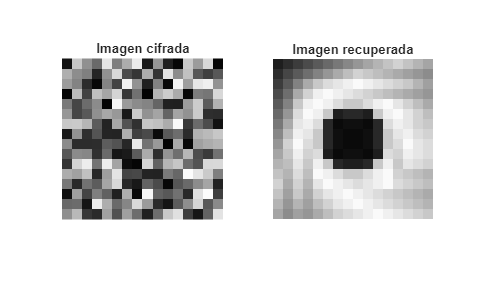

%% cargar imagen cifrada
img_diff = img_diff1;

[filas,columnas] = size(img_diff);

%% ===== DESHACER DIFUSIÓN =====

seed_diff = 0.81;

img_perm = inverseChaoticDiffusion(img_diff, seed_diff);

%% ===== SEPARAR PLANOS DE BITS =====

bitplanes = zeros(filas,columnas,8);

for k=1:8
    
    bitplanes(:,:,k) = bitget(img_perm,9-k);
    
end

%% ===== DESHACER INTER-BIT =====

bitplanes = inverseInterBitPermutation(bitplanes, pairs);

%% ===== DESHACER INTRA-BIT =====

seeds = [0.5 0.52 0.53 0.6 0.37 0.46 0.38 0.61];

for k=1:8
    
    S = logisticSequence(seeds(k),3.99999,1000,filas*columnas);
    
    [~,perm] = sort(S,'ascend');
    
    bitplanes(:,:,k) = inverseIntraBitPermutation(bitplanes(:,:,k),perm);
    
end

%% ===== RECONSTRUIR IMAGEN =====

img_original = zeros(filas,columnas,'uint8');

for k=1:8
    
    img_original = img_original + uint8(bitplanes(:,:,k))*2^(8-k);
    
end

%% mostrar resultado

figure

subplot(1,2,1)
imshow(img_diff)
title("Imagen cifrada")

subplot(1,2,2)
imshow(img_original)
title("Imagen recuperada")